# XTD_C1: XTD vs Chance

% fileDirs = [{'D:\PFC\GE11_Session132'},...
%     {'D:\PFC\GE13_Session083'},...
%     {'D:\PFC\GE14_Session123'},...
%     {'D:\PFC\GE17_Session095'},...
%     {'D:\PFC\GE24_Session096'}];
fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);
nanWmap = rbDivMap;
nanWmap(1,:) = [1,1,1];

## Compile Data Across Rats

prevTrlLat = cell(1,4);
trialLightLat = cell(1,4);
pokeInLat = cell(1,4);
rwdSigLat = cell(1,4);
pokeOutLat = cell(1,4);
rwdLat = cell(1,4);
nxtTrlLat = cell(1,4);
for ani = 1:length(fileDirs)
    aniDta = load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'xtdHR_Real', 'xtdD_Real',...
        'xtdHR_ChanceFull', 'xtdD_ChanceFull', 'xtdHR_ChancePos', 'xtdD_ChancePos');   
    fns = fieldnames(aniDta);
    if ani == 1
        for fn = 1:length(fns)
            eval(sprintf('%s = aniDta.%s;', fns{fn}, fns{fn}));
        end
    else
        for d = 1:numel(xtdHR_Real)
            for fn = 1:length(fns)
                eval(sprintf('%s{d} = cat(3,%s{d}, aniDta.%s{d});', fns{fn}, fns{fn}, fns{fn}));
            end
        end
    end
    load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'trialInfo', 'mlb');
    cur_TrialInfo = cell2mat(trialInfo(cellfun(@(a)~isempty(a),trialInfo))');
    for pos = 1:mlb.seqLength
        curPosLog = [cur_TrialInfo.Position]==pos;
        if strcmp(mlb.alignments{1}, 'PokeIn')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeInIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
        elseif strcmp(mlb.alignmnents{1}, 'PokeOut')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]*-1];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeOutIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
        end
    end
end

## Plot Things

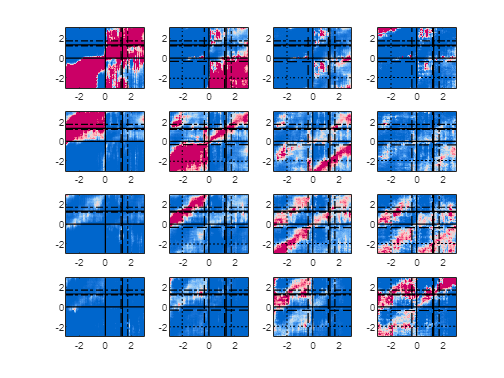

figure; 
spNdxs = reshape(1:mlb.seqLength^2, [mlb.seqLength, mlb.seqLength]);
for trlPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        subplot(mlb.seqLength, mlb.seqLength, spNdxs(trlPos,decPos));
        imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, median(xtdHR_Real{trlPos,trlPos,trlPos,decPos},3,'omitnan'), [0 0.5]);
        hold on;
        plot(repmat(median(prevTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 0.5);        
        plot(get(gca, 'xlim'), repmat(median(prevTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 0.5);
        plot(repmat(median(trialLightLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(trialLightLat{trlPos}), [1,2]), '--k', 'linewidth', 1);
        plot(repmat(median(pokeInLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeInLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdSigLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdSigLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(pokeOutLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeOutLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdLat{trlPos}), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(nxtTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 0.5);        
        plot(get(gca, 'xlim'), repmat(median(nxtTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 0.5);
        

        colormap(rbDivMap);
        set(gca,'ydir', 'normal');
    end
end

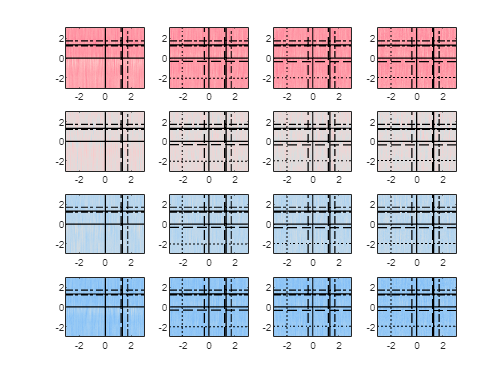

figure; 
spNdxs = reshape(1:mlb.seqLength^2, [mlb.seqLength, mlb.seqLength]);
for trlPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        subplot(mlb.seqLength, mlb.seqLength, spNdxs(trlPos,decPos));
        imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, median(xtdHR_ChanceFull{trlPos,trlPos,trlPos,decPos},3,'omitnan'), [0 0.5]);
        hold on;
        plot(repmat(median(prevTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 0.5);        
        plot(get(gca, 'xlim'), repmat(median(prevTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 0.5);
        plot(repmat(median(trialLightLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(trialLightLat{trlPos}), [1,2]), '--k', 'linewidth', 1);
        plot(repmat(median(pokeInLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeInLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdSigLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdSigLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(pokeOutLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeOutLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdLat{trlPos}), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(nxtTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 0.5);        
        plot(get(gca, 'xlim'), repmat(median(nxtTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 0.5);
        

        colormap(rbDivMap);
        set(gca,'ydir', 'normal');
    end
end

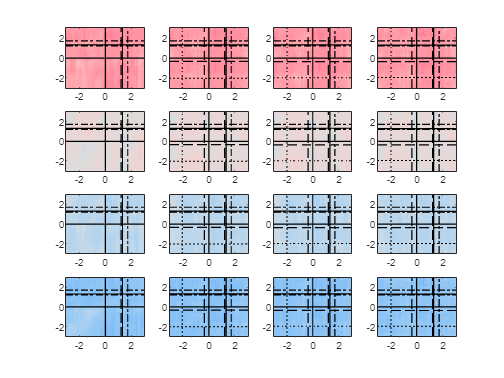

figure; 
spNdxs = reshape(1:mlb.seqLength^2, [mlb.seqLength, mlb.seqLength]);
for trlPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        subplot(mlb.seqLength, mlb.seqLength, spNdxs(trlPos,decPos));
        imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, median(xtdHR_ChancePos{trlPos,trlPos,trlPos,decPos},3,'omitnan'), [0 0.5]);
        hold on;
        plot(repmat(median(prevTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 0.5);        
        plot(get(gca, 'xlim'), repmat(median(prevTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 0.5);
        plot(repmat(median(trialLightLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(trialLightLat{trlPos}), [1,2]), '--k', 'linewidth', 1);
        plot(repmat(median(pokeInLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeInLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdSigLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdSigLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(pokeOutLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeOutLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdLat{trlPos}), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(nxtTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 0.5);        
        plot(get(gca, 'xlim'), repmat(median(nxtTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 0.5);
        

        colormap(rbDivMap);
        set(gca,'ydir', 'normal');
    end
end

## Plot Significant Values

% Plot significance thresholded plots
figure; 
spNdxs = reshape(1:mlb.seqLength^2, [mlb.seqLength, mlb.seqLength]);
tStatVals = cell(mlb.seqLength, mlb.seqLength,2);
sigVals = cell(mlb.seqLength, mlb.seqLength,2);
realMnVals = cell(mlb.seqLength, mlb.seqLength);
for trlPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        curRealVals = xtdHR_Real{trlPos,trlPos,trlPos,decPos};
        curChanceFull = mean(xtdHR_ChanceFull{trlPos,trlPos,trlPos,decPos},3,'omitnan');
        curChancePos = mean(xtdHR_ChancePos{trlPos,trlPos,trlPos,decPos},3,'omitnan');

        curTfull = nan(size(curChanceFull));
        curPfull = nan(size(curChanceFull));
        curTpos = nan(size(curChancePos));
        curPpos = nan(size(curChancePos));
        
        for tst = 1:length(mlb.obsvTimeVect)
            for trn = 1:length(mlb.obsvTimeVect)
                temp_RealVals = squeeze(curRealVals(tst,trn,:));
                [~,curPfull(tst,trn),~,fullStats] = ttest(temp_RealVals, curChanceFull(tst,trn), 'Tail', 'Right');
                curTfull(tst,trn) = fullStats.tstat;
                [~,curPpos(tst,trn),~,posStats] = ttest(temp_RealVals, curChancePos(tst,trn), 'Tail', 'Right');
                curTpos(tst,trn) = posStats.tstat;
            end
        end
        realMnVals{trlPos,decPos} = mean(curRealVals,3,'omitnan');
        tStatVals{trlPos,decPos,1} = curTfull;
        tStatVals{trlPos,decPos,2} = curTpos;
        sigVals{trlPos,decPos,1} = curPfull;
        sigVals{trlPos,decPos,2} = curPpos;
    end
end

## Plot Vals

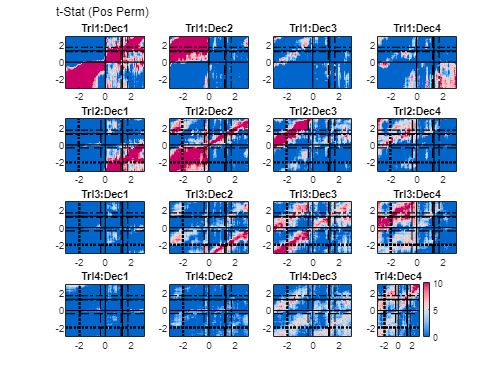

% plotVals = realMnVals;   plotLims = [0 0.5]; tit = 'Mean Decoding';
% plotVals = tStatVals(:,:,1);   plotLims = [0 10]; tit = 't-Stat (Full Perm)';
plotVals = tStatVals(:,:,2);   plotLims = [0 10]; tit = 't-Stat (Pos Perm)';
% plotVals = sigVals(:,:,1);     plotLims = [0 1]; tit = 'p-Val (Full Perm)';
% plotVals = sigVals(:,:,2);     plotLims = [0 1]; tit = 'p-Val (Pos Perm)';

figure;
for trlPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength

        subplot(mlb.seqLength, mlb.seqLength, spNdxs(decPos,trlPos));
        imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, plotVals{trlPos,decPos}, plotLims);
        hold on;
        plot(repmat(median(prevTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);        
        plot(get(gca, 'xlim'), repmat(median(prevTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 2);
        plot(repmat(median(trialLightLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(trialLightLat{trlPos}), [1,2]), '--k', 'linewidth', 1);
        plot(repmat(median(pokeInLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeInLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdSigLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdSigLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(pokeOutLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeOutLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdLat{trlPos}), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(nxtTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);        
        plot(get(gca, 'xlim'), repmat(median(nxtTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 2);

        colormap(rbDivMap);
        set(gca,'ydir', 'normal');
        title(sprintf('Trl%i:Dec%i',trlPos,decPos));
    end
end
colorbar;
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', tit, 'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');

## Real Val Sig Mapped

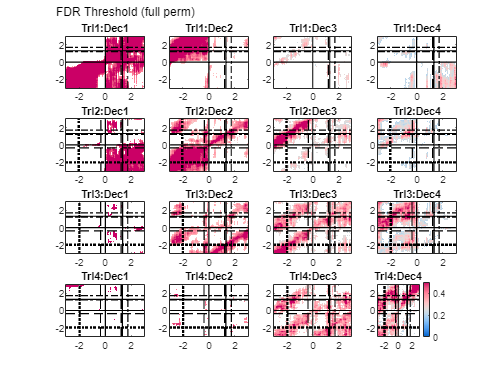

sigMask = sigVals(:,:,1);
% sigMask = sigVals(:,:,2);

figure;
for trlPos = 1:mlb.seqLength
    for decPos = 1:mlb.seqLength
        subplot(mlb.seqLength, mlb.seqLength, spNdxs(decPos,trlPos));
        tempReal = realMnVals{trlPos,decPos};
        tempSigMask = sigMask{trlPos,decPos};
%         sigLog = tempSigMask>0.05;
%         sigLog = tempSigMask>(0.05/numel(tempSigMask));
%         sigLog = tempSigMask>(0.05/length(mlb.obsvTimeVect));
        [~,q] = mafdr(tempSigMask(:));
        sigLog = reshape(q,size(tempSigMask))>0.05;
        tempReal(sigLog) = nan;

        imagesc(mlb.obsvTimeVect, mlb.obsvTimeVect, tempReal, [0 0.5]);
        hold on;
        plot(repmat(median(prevTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);        
        plot(get(gca, 'xlim'), repmat(median(prevTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 2);
        plot(repmat(median(trialLightLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(trialLightLat{trlPos}), [1,2]), '--k', 'linewidth', 1);
        plot(repmat(median(pokeInLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeInLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdSigLat{trlPos}), [1,2]), get(gca,'ylim'), '--k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdSigLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(pokeOutLat{trlPos}), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(pokeOutLat{trlPos}), [1,2]), '-k', 'linewidth', 1);
        plot(repmat(median(rwdLat{trlPos}), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 1);        
        plot(get(gca, 'xlim'), repmat(median(rwdLat{trlPos}), [1,2]), '-.k', 'linewidth', 1);
        plot(repmat(median(nxtTrlLat{trlPos}), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);        
        plot(get(gca, 'xlim'), repmat(median(nxtTrlLat{trlPos}), [1,2]), ':k', 'linewidth', 2);

        colormap(nanWmap);
        set(gca,'ydir', 'normal');
        title(sprintf('Trl%i:Dec%i',trlPos,decPos));
    end
end
colorbar;
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
        'String', 'FDR Threshold (full perm)', 'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');